# Features for Random Forest

## Pre-processing & Initialization

### Initialize Directories

% inputs
main_dir = '~/Desktop/Thesis/sharing-github-nature-medicine/BRAVEHEART-main/Example ECGs/12-lead-mat/data';
data_dir = fullfile(main_dir, 'data'); % directory for all data

filename = '/JS10014.mat';
patitent_name = filename(2: end-4)

patitent_name = 'JS10014'

fullpath = fullfile(data_dir, filename); % directory for each patient

% outputs
output_dir = fullfile(main_dir, 'features', patitent_name);
output_dir = strcat(output_dir, '.csv');
output = struct();

### Load Data & Save Plots

data = load(fullpath);
data = data.data;

### Hyperparameters

age = data.age;
gender = data.sex;

### Extract Median Beats & Indices

Fs = data.median_12L.hz; % unit = data.median_12L.units;

lead_i = data.median_12L.I;
lead_ii = data.median_12L.II;
lead_iii = data.median_12L.III;
avf = data.median_12L.avF;
avl = data.median_12L.avL;
avr = data.median_12L.avR;
v1 = data.median_12L.V1;
v2 = data.median_12L.V2;
v3 = data.median_12L.V3;
v4 = data.median_12L.V4;
v5 = data.median_12L.V5;
v6 = data.median_12L.V6;

lead_morph = data.lead_morph;

lead_names = {'L1', 'avL', 'V1', 'V2', 'V3', 'V4', 'V5', 'V6'};

% Loop through each set of lead indices
for lead_name = lead_names
    variable_name_prefix = char(lead_name);

    % Dynamic variable names for the locations
    location_suffixes = {'_p_loc', '_q_loc', '_r_loc', '_s_loc', '_t_loc', '_j_loc'};
    
    % Process each location for the current lead
    for suffix = location_suffixes
        location_var_name = [variable_name_prefix, suffix{1}];
        
        % Process the indices for the current location
        processed_indices = median_or_warn(location_var_name, lead_morph.(location_var_name));
        
        % Update the lead_morph structure with the processed indices
        lead_morph.(location_var_name) = processed_indices;
    end
end

Non-singleton found in avL_r_loc: [46;47]
Non-singleton found in V1_r_loc: [81;356;368]
Non-singleton found in V2_r_loc: [83;257;263;274;276;277]
Non-singleton found in V3_r_loc: [39;112;113;390;460]
Non-singleton found in V4_r_loc: [45;46]


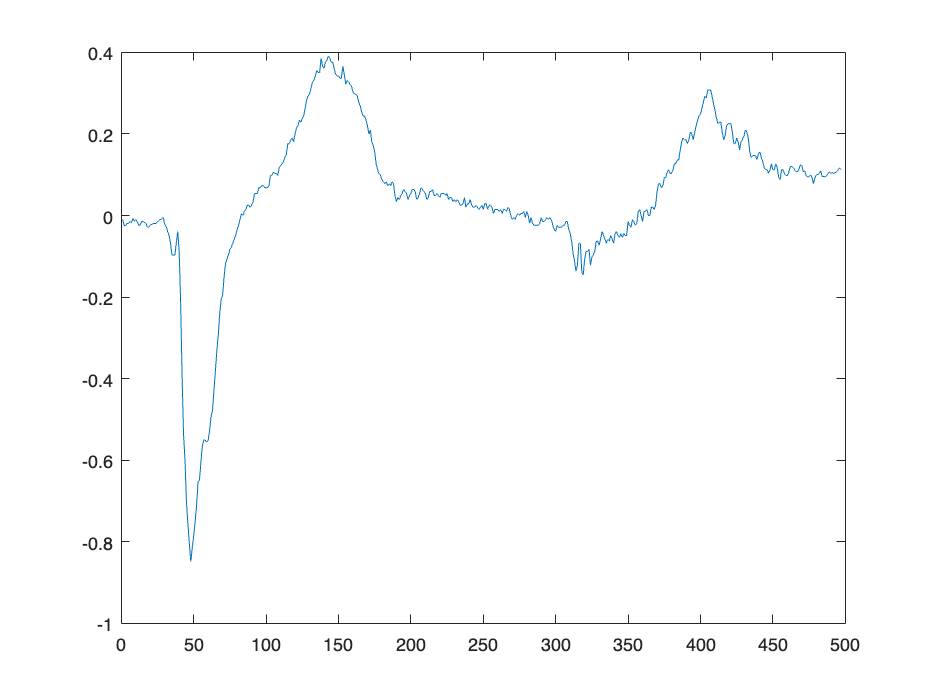


plot(v2)

### Manual Adjustment

% lead_morph.avF_r_loc = 32;
% lead_morph.avF_s_loc = 52;
% lead_morph.avF_q_loc = 26;
% 
% lead_morph.V1_r_loc = 22;
% lead_morph.V1_s_loc = 43;
% lead_morph.V1_q_loc = 10;

% lead_morph.L1_r_loc = 51;
% lead_morph.V3_r_loc = 26;
% lead_morph.V4_r_loc = 27;

### Re-assignment

% Accessing processed indices directly from the lead_morph structure for L1 lead
L1_p_indices = lead_morph.L1_p_loc;
L1_q_indices = lead_morph.L1_q_loc;
L1_r_indices = lead_morph.L1_r_loc;
L1_s_indices = lead_morph.L1_s_loc;
L1_t_indices = lead_morph.L1_t_loc;
L1_j_indices = lead_morph.L1_j_loc;
L1_indices = [L1_p_indices, L1_q_indices, L1_r_indices, L1_s_indices, L1_t_indices, L1_j_indices];

% avL lead
avL_p_indices = lead_morph.avL_p_loc;
avL_q_indices = lead_morph.avL_q_loc;
avL_r_indices = lead_morph.avL_r_loc;
avL_s_indices = lead_morph.avL_s_loc;
avL_t_indices = lead_morph.avL_t_loc;
avL_j_indices = lead_morph.avL_j_loc;
avL_indices = [avL_p_indices, avL_q_indices, avL_r_indices, avL_s_indices, avL_t_indices, avL_j_indices];

% V1 lead
V1_p_indices = lead_morph.V1_p_loc;
V1_q_indices = lead_morph.V1_q_loc;
V1_r_indices = lead_morph.V1_r_loc;
V1_s_indices = lead_morph.V1_s_loc;
V1_t_indices = lead_morph.V1_t_loc;
V1_j_indices = lead_morph.V1_j_loc;
V1_indices = [V1_p_indices, V1_q_indices, V1_r_indices, V1_s_indices, V1_t_indices, V1_j_indices];

% V2 lead
V2_p_indices = lead_morph.V2_p_loc;
V2_q_indices = lead_morph.V2_q_loc;
V2_r_indices = lead_morph.V2_r_loc;
V2_s_indices = lead_morph.V2_s_loc;
V2_t_indices = lead_morph.V2_t_loc;
V2_j_indices = lead_morph.V2_j_loc;
V2_indices = [V2_p_indices, V2_q_indices, V2_r_indices, V2_s_indices, V2_t_indices, V2_j_indices];

% V3 lead
V3_p_indices = lead_morph.V3_p_loc;
V3_q_indices = lead_morph.V3_q_loc;
V3_r_indices = lead_morph.V3_r_loc;
V3_s_indices = lead_morph.V3_s_loc;
V3_t_indices = lead_morph.V3_t_loc;
V3_j_indices = lead_morph.V3_j_loc;
V3_indices = [V3_p_indices, V3_q_indices, V3_r_indices, V3_s_indices, V3_t_indices, V3_j_indices];


% V4 lead
V4_p_indices = lead_morph.V4_p_loc;
V4_q_indices = lead_morph.V4_q_loc;
V4_r_indices = lead_morph.V4_r_loc;
V4_s_indices = lead_morph.V4_s_loc;
V4_t_indices = lead_morph.V4_t_loc;
V4_j_indices = lead_morph.V4_j_loc;
V4_indices = [V4_p_indices, V4_q_indices, V4_r_indices, V4_s_indices, V4_t_indices, V4_j_indices];

% V5 lead
V5_p_indices = lead_morph.V5_p_loc;
V5_q_indices = lead_morph.V5_q_loc;
V5_r_indices = lead_morph.V5_r_loc;
V5_s_indices = lead_morph.V5_s_loc;
V5_t_indices = lead_morph.V5_t_loc;
V5_j_indices = lead_morph.V5_j_loc;
V5_indices = [V5_p_indices, V5_q_indices, V5_r_indices, V5_s_indices, V5_t_indices, V5_j_indices];

% V6 lead
V6_p_indices = lead_morph.V6_p_loc;
V6_q_indices = lead_morph.V6_q_loc;
V6_r_indices = lead_morph.V6_r_loc;
V6_s_indices = lead_morph.V6_s_loc;
V6_t_indices = lead_morph.V6_t_loc;
V6_j_indices = lead_morph.V6_j_loc;
V6_indices = [V6_p_indices, V6_q_indices, V6_r_indices, V6_s_indices, V6_t_indices, V6_j_indices];

data.lead_morph = lead_morph;

## Extract Features From Batch Processing

### VCG_Calc

output.QRSd = data.geh.qrs_int;
output.tpte = data.geh.vm_tpeak_tend_abs_diff;
output.txzQRSaxis = data.geh.q_peak_az;
output.fpTaxis = data.geh.t_peak_el;
output.mfpQRSaxis = data.geh.q_peak_el;
output.mQRSTangle = data.geh.qrst_angle_area;
output.QRSTangle = data.geh.qrst_angle_peak;
output.TMD = data.geh.vcg_length_t;

### Lead_Morphology

output.tamp_i = lead_morph.L1_t_max;
output.tamp_ii = lead_morph.L2_t_max;
output.tamp_iii = lead_morph.L3_t_max;
output.tamp_avr = lead_morph.avR_t_max;
output.tamp_avl = lead_morph.avL_t_max;
output.tamp_avf = lead_morph.avF_t_max;
output.tamp_v1 = lead_morph.V1_t_max;
output.tamp_v2 = lead_morph.V2_t_max;
output.tamp_v3 = lead_morph.V3_t_max;
output.tamp_v4 = lead_morph.V4_t_max;
output.tamp_v5 = lead_morph.V5_t_max;
output.tamp_v6 = lead_morph.V6_t_max;
output.Tamp = max([output.tamp_i, output.tamp_ii, output.tamp_iii, output.tamp_avr, output.tamp_avl, output.tamp_avf, output.tamp_v1, output.tamp_v2, output.tamp_v3, output.tamp_v4, output.tamp_v5, output.tamp_v6]);
output.pcaTamp = lead_morph.VM_t_max;
output.ramp_iii = lead_morph.L3_r_wave;
output.ramp_avl = lead_morph.avL_r_wave;
output.ramp_v4 = lead_morph.V4_r_wave;
output.TrelAmp = (lead_morph.VM_t_max - lead_morph.VM_r_wave) / lead_morph.VM_r_wave;

### VCG_Morphology

output.TCRT = data.vcg_morph.TCRT;
output.TCRTangle = data.vcg_morph.TCRT_angle;

### Others

output.hr = data.hr;
output.age = age;
output.gender = gender;
output.mi = data.mi;
output.rmsMin = min(data.median_vcg.VM);
output.rmsVar = var(data.median_vcg.VM);

## Feature Computation

### Prepare Data for Selvester Score

data.selvester_prep = Qrs_Characteristic(data.median_12L, lead_morph, gender);

Q index: 25 ; R_index: 47; S_index: 58; Q start: 8; Q end: 29; R start: 29; R end: 54; 
Q index: 38 ; R_index: 60; S_index: 61; Q start: 93; Q end: 27; R start: 50; R end: 50; 
Q index: 86 ; R_index: 87; S_index: Q index: 41 ; R_index: 60; S_index: 110; Q start: 8; Q end: 52; R start: 52; R end: 87; 
Q index: 26 ; R_index: 47; S_index: 58; Q start: 18; Q end: 28; R start: 28; R end: 53; 
Q index: 4 ; R_index: 356; S_index: 50; Q start: 1; Q end: 71; R start: 71; R end: ; 
Q index: 10 ; R_index: 269; S_index: 50; Q start: 8; Q end: 85; R start: 85; R end: ; 
Q index: 17 ; R_index: 113; S_index: 64; Q start: 1; Q end: 20; R start: 20; R end: ; 
Q index: 29 ; R_index: 46; S_index: 65; Q start: 7; Q end: 35; R start: 35; R end: 62; 
Q index: 27 ; R_index: 48; S_index: 67; Q start: 9; Q end: 35; R start: 35; R end: 66; 
Q index: 29 ; R_index: 48; S_index: 70; Q start: 3; Q end: 36; R start: 36; R end: 69; 


### ST_80

% index
% index_shift = 80 / Fs * 1000 / 2

index_shift = 800

index_shift = 4;
output.st80_i = lead_i(lead_morph.L1_j_loc + index_shift);

Index exceeds the number of array elements. Index must not exceed 497.

output.st80_iii = lead_iii(lead_morph.L3_j_loc + index_shift);
output.st80_avl = avl(lead_morph.avL_j_loc + index_shift);
output.st80_avf = avf(lead_morph.avF_j_loc + index_shift);
output.st80_v1 = v1(lead_morph.V1_j_loc + index_shift);
output.st80_v2 = v2(lead_morph.V2_j_loc + index_shift);
output.st80_v3 = v3(lead_morph.V3_j_loc + index_shift);
output.st80_v4 = v4(lead_morph.V4_j_loc + index_shift);
output.st80_v5 = v5(lead_morph.V5_j_loc + index_shift);
output.st80_v6 = v6(lead_morph.V6_j_loc + index_shift);

### Concave Amplitude Count

anterior_lead_index = {V1_indices, V2_indices, V3_indices, V4_indices};
anterior_leads = {v1, v2, v3, v4};
output.antConcaveAmp = concave_amp_count(anterior_lead_index, anterior_leads);

lateral_lead_index = {L1_indices, avL_indices, V5_indices, V6_indices};
lateral_leads = {lead_i, avl, v5, v6};
output.latConcaveAmp = concave_amp_count(lateral_lead_index, lateral_leads);

### T Axis

t_vector = [data.geh.svg_x, data.geh.svg_y, data.geh.svg_z];
t_vector = t_vector / norm(t_vector, 2);

project_t = t_vector * [1/sqrt(3); 1/sqrt(3) ; -1/sqrt(3)];
TaxisDev = t_vector - project_t * [1/sqrt(3), 1/sqrt(3), -1/sqrt(3)];
output.spatialTaxisDev = norm(TaxisDev, 2);

### Properties before 1st Inflection Point

% TO-DO: use all 12-leads;
% retreive wave before T_peak
temp_wave = lead_ii(1 : lead_morph.L2_t_loc);

dy2dx2 = diff(diff(temp_wave));
inflection_point_indices = find(dy2dx2(1:end-1).* dy2dx2(2:end) < -0.0001);
inflection_point = inflection_point_indices(1);

% Global Tpeak Amplitude
output.TampInfl1 = lead_ii(inflection_point);

% Frontal Tpeak Axis & Magnitude
output.fpTinfl1Axis = median(atan2d(lead_ii(1: inflection_point)', lead_ii(1: inflection_point)'));
output.fpTinfl1Mag = median(hypot(lead_ii(1: inflection_point)', lead_ii(1: inflection_point)'));

### JT Interval

% TO-DO: use all 12-leads; check calculations
output.JTc = (lead_morph.L2_t_loc - lead_morph.L2_j_loc) / Fs * 1000;

% PR interval omitted

### J - T peak Area

output.jt_anterior = median([lead_morph.V1_jt_area lead_morph.V2_jt_area lead_morph.V3_jt_area lead_morph.V4_jt_area]);
output.jt_lateral = median([lead_morph.L1_jt_area lead_morph.avL_jt_area lead_morph.V5_jt_area lead_morph.V6_jt_area]);

### Ventricular Activation Time

output.vat_ii = median_or_warn('L2_vat', lead_morph.L2_vat);
output.vat_iii = median_or_warn('L3_vat', lead_morph.L3_vat);
output.vat_v2 = median_or_warn('V2_vat', lead_morph.V2_vat);
output.vat_v4 = median_or_warn('V4_vat', lead_morph.V4_vat);

### Nondipolar Voltage (NDPV)

nondipolar = data.vcg_morph.eight_lead_remain_E;
% plot(nondipolar)
R_index = data.medianbeat.QRS;
T_index = data.medianbeat.T;
S_index = data.medianbeat.S;

st_range = lead_ii(data.medianbeat.S : data.medianbeat.T);
% derivative = diff(st_range);
[~, DerivativeIndex] = max(diff(st_range < 0));
J_index = data.medianbeat.S + DerivativeIndex;


output.STNDPV = sqrt(mean(sum(nondipolar(S_index: T_index) .^ 2)));
output.RNDPV = nondipolar(R_index);
output.JNDPV = nondipolar(J_index);
output.TNDPV = nondipolar(T_index);

output.pctSTNDPV = median(nondipolar(S_index: T_index) ./ data.median_vcg.VM(S_index: T_index));
output.pctRNDPV = output.RNDPV / data.median_vcg.VM(R_index);
output.pctJNDPV = output.JNDPV / data.median_vcg.VM(J_index);
output.pctTNDPV = output.TNDPV / data.median_vcg.VM(T_index);

### PCA Ratios

#### Ratios from Modifiying BREAVEHEART

output.PCA1 = data.vcg_morph.eight_lead_s1_var;
output.PCA2 = data.vcg_morph.eight_lead_s2_var;
output.PCA3 = data.vcg_morph.eight_lead_s3_var;

output.QRS_PCAratio = data.vcg_morph.qrs_S2 / data.vcg_morph.qrs_S1;
output.T_PCAratio = data.vcg_morph.t_S2 / data.vcg_morph.t_S1;

#### Hand Compute

% TO-DO: [STT wave] QRS offset, J point?
X1 = [lead_i(J_index: J_index + 10) lead_ii(J_index: J_index + 10) v1(J_index: J_index + 10) v2(J_index: J_index + 10) v3(J_index: J_index + 10) v4(J_index: J_index + 10) v5(J_index: J_index + 10) v6(J_index: J_index + 10)];
X2 = [lead_i(S_index: data.medianbeat.Tend) lead_ii(S_index: data.medianbeat.Tend) v1(S_index: data.medianbeat.Tend) v2(S_index: data.medianbeat.Tend) v3(S_index: data.medianbeat.Tend) v4(S_index: data.medianbeat.Tend) v5(S_index: data.medianbeat.Tend) v6(S_index: data.medianbeat.Tend)];

output.J_PCAratio = simplified_svd_8lead(X1);
output.STT_PCAratio = simplified_svd_8lead(X2);

### More on T-wave Morphology Dispersion

output.TMDpre = data.geh.vcg_length_t_pre;
output.TMDpost = data.geh.vcg_length_t_post;

### T Asymmetric Score

range = data.median_vcg.VM(data.medianbeat.S : data.medianbeat.T);

derivative = diff(range);
[~, zeroDerivativeIndex] = min(abs(derivative));
T_on = data.medianbeat.S + zeroDerivativeIndex - 1;

T_wave = data.median_vcg.VM(T_on : data.medianbeat.Tend);

T_max = data.medianbeat.T - T_on;
T_end = data.medianbeat.Tend - T_on;

derivative = diff(T_wave);
T_asc = derivative(1: T_max) / max(abs(derivative(1: T_max)));
T_des =  - derivative(T_max + 1: end) / max(abs(derivative(T_max + 1: end)));


T_total = zeros(min(length(T_des), length(T_asc)), 1);
T_total = T_asc(min(length(T_des), length(T_asc))) - T_des(min(length(T_des), length(T_asc)));
output.Tasym = mean((T_asc - T_total) .^ 2);

figure();
plot(T_wave)
hold on;
plot(T_asc)
hold on;
plot(T_total)
hold on;
legend("T wave", "derivative of ascending", "descending derivative after modification")
hold off;

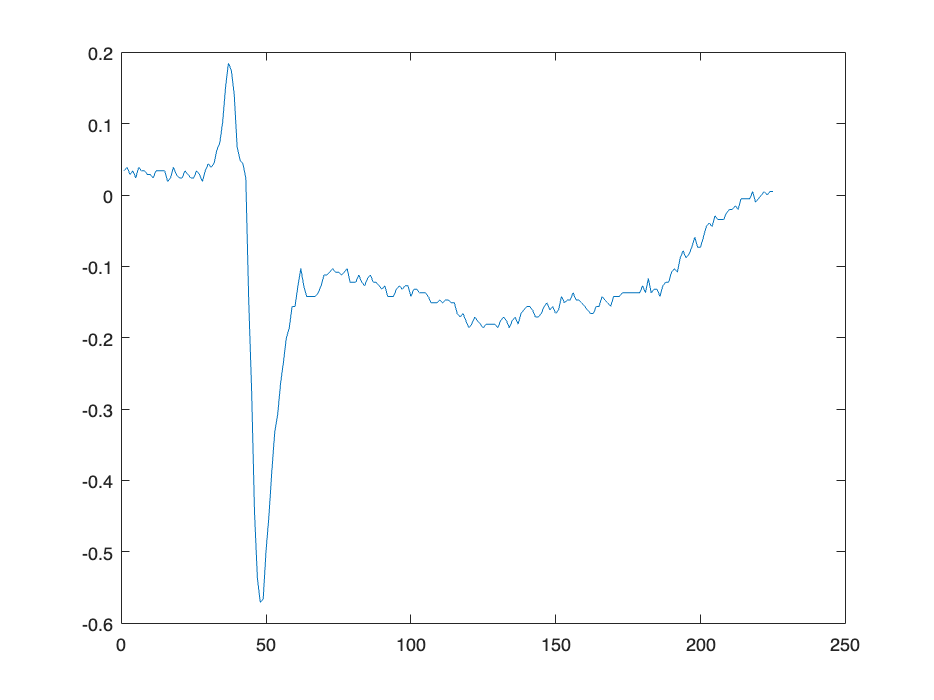

% disp('The program is paused for QRS score adjustment. Please modify variables as needed.');
% disp('Type ''continue'' and press Enter to resume.');
% 
% % Wait for a specific user input to resume
% userInput = input('Command: ', 's');
% while ~strcmp(userInput, 'continue')
% 
%     delimiters = '[;,|:]';
%     slicedParts = regexp(userInput, delimiters, 'split');
% 
%     % Displaying the results
%     for i = 1:length(slicedParts)
%         if mod(i, 2) == 1
%             var = slicedParts{i}
%             new_value = slicedParts{i+1};
% 
%             qrs_char.(var) = str2double(new_value);
%         end
%     end
% 
%     userInput = input('Command: ', 's');
% 
% end
figure;
plot(v1)

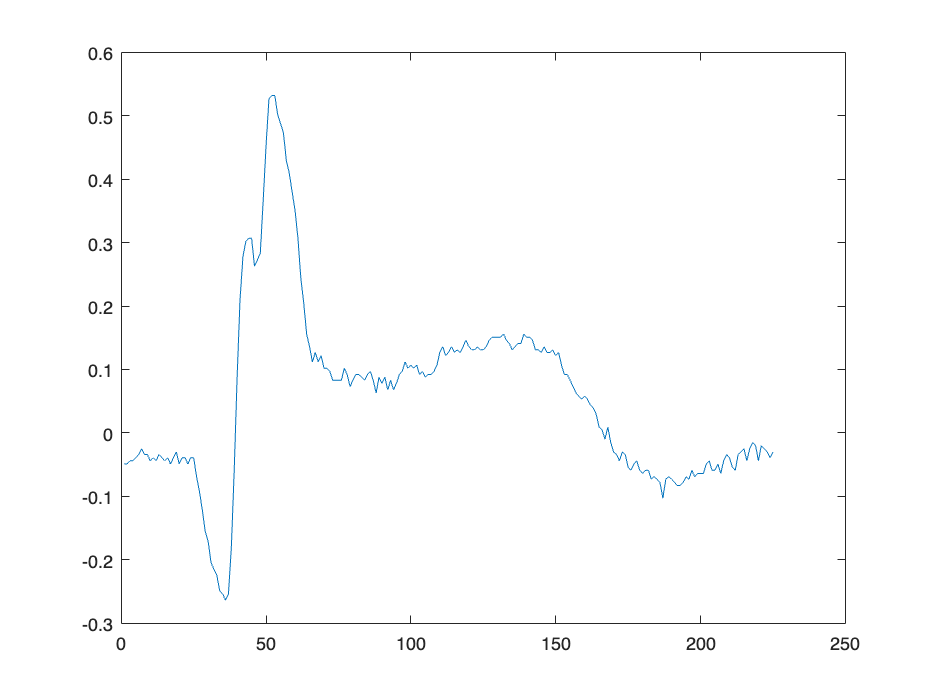


figure;
plot(avf)

### Q Duration

output.q_dur = data.selvester_prep.avF_Q_duration;

### Selvester Score (MI size)

RS slope is -5.945455e-03 
QRS interval is 94 
QRS axis is 2.828873e+01

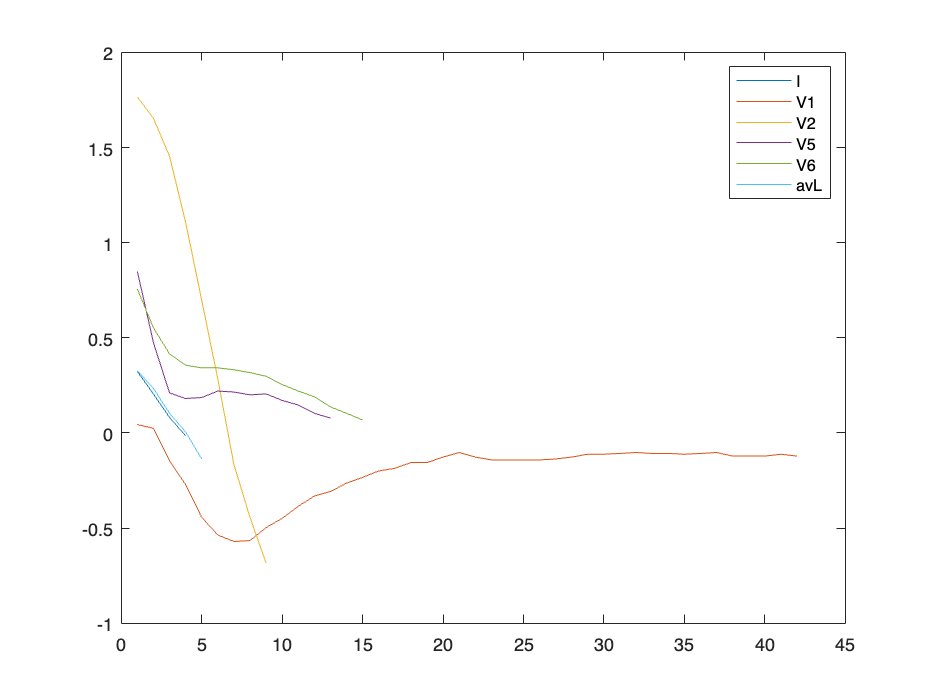

irregular_qrs = 0

category = 'No confounders'

MIsz = 11

output.MIsz = selvester(data, age, gender);

## Save Results

writetable(struct2table(output), output_dir);